BF_40xImageProcessingTestys

I0 = BF_1_MMStack_Default_9_ome;
% BG = BG1_MMStack_Default_ome;
%2020-04-10-PAO1 microfluid flow cell test pl
% % backGround Correction
% [I0,~]=backGroundCorrection(I0,BG,'16bit');

1


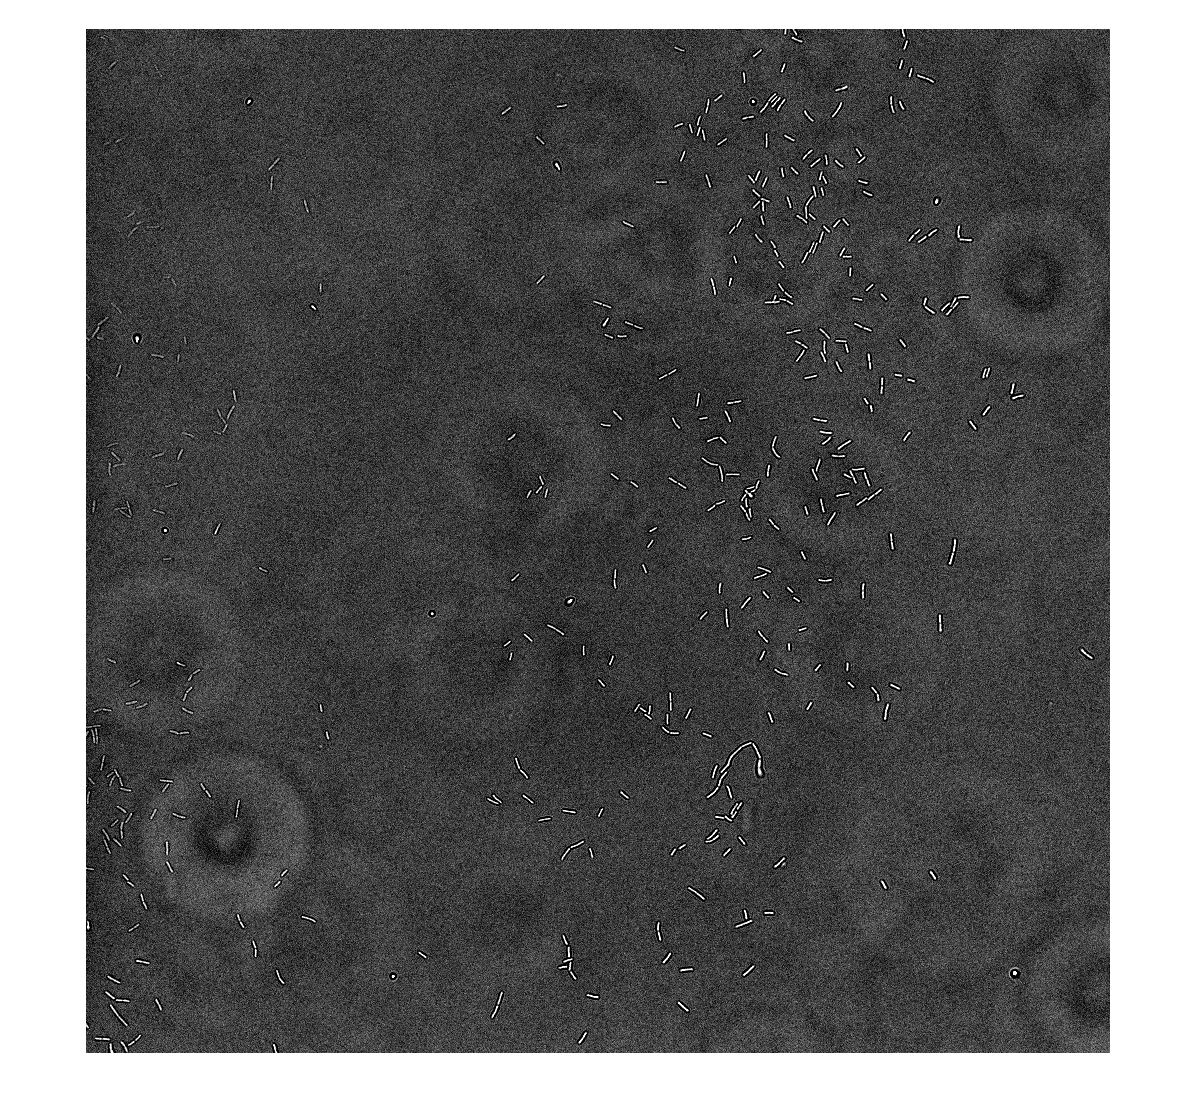

% imshow(I0,[]);

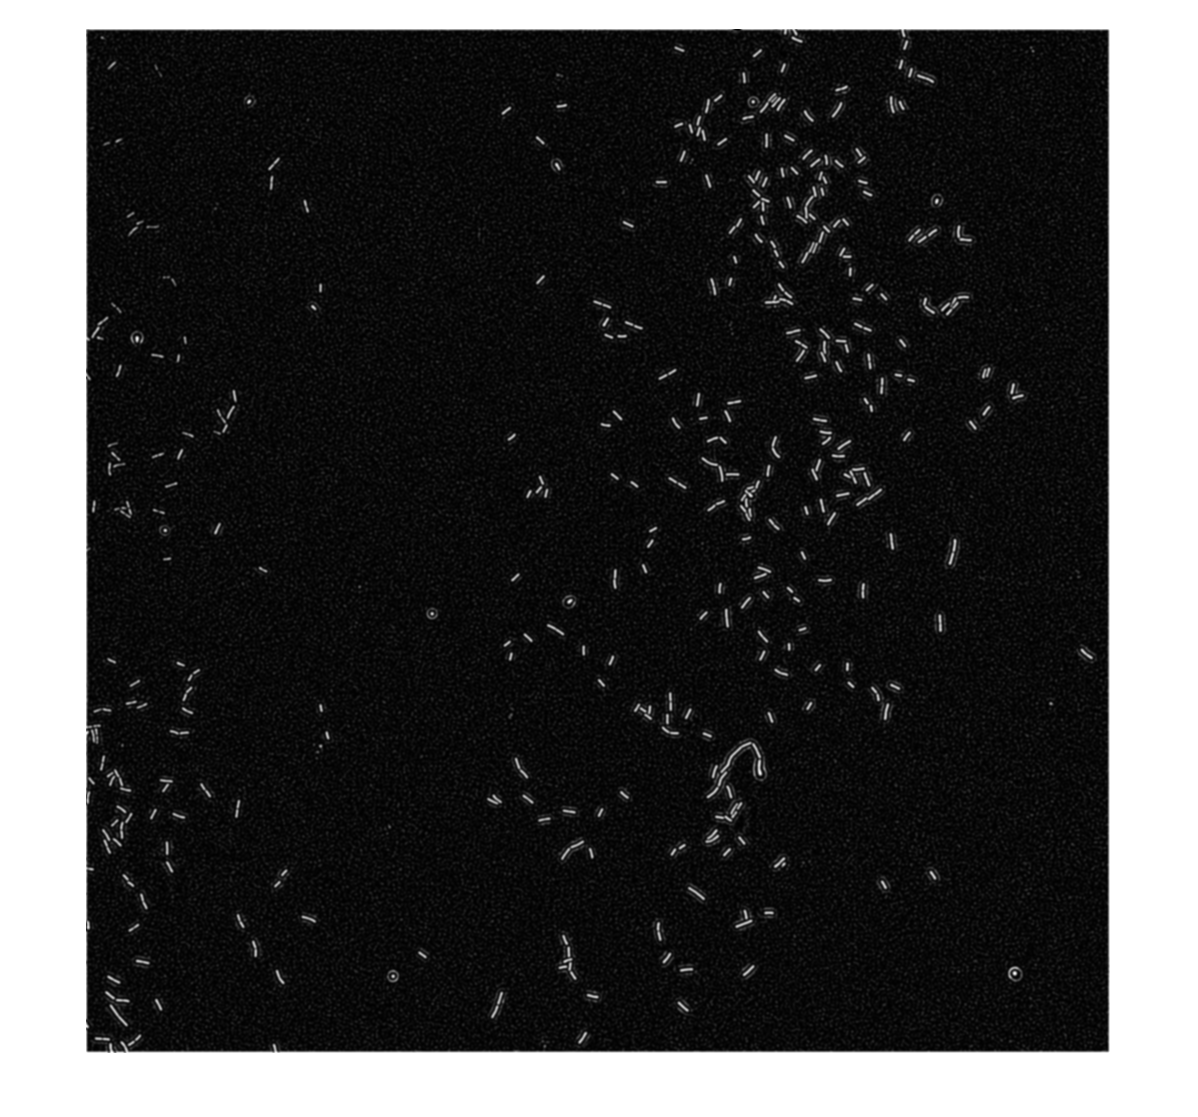

% convert 8 bit image
I = uint8(double(I0-min(I0(:)))/double(max(I0(:))-min(I0(:)))*255);



edgeFilter=(ones(5,5)).*-1;edgeFilter(3,3)=24;%created edgefilter
I1 = imgaussfilt(I, 2);
I1 = imfilter(I1,edgeFilter);
I1 = imgaussfilt(I1, 2);
imshow(I1,[]);